## Angstrom experiment

Works with TEC_V9.mlapp or TEC_V10.mlapp & SerialTestNov8a.ino which sinusoidally varies Tset and measures the temperature at multiple locations along a cylinder of metal.

PlotAngstromExp5TPeriod60.mlx extracts the temperature at 5 locations plus at the TEC vs time data for sinusoidally varying Tset. 

The period = 60 sec is hard coded in. Copy the entire program, change the period and rename it to analyze the other periods.

All the Arduino controls are printed whenever a control parameter is changed. This information be used to find the time intervals over which the Tset parameters did not change for analysis of the steady state temperature distribution along the rod.

#### All this code was written with a lot of help from ChatGPT. However, it took quite a few iterations to get exactly what I wanted. There is no way I could have done this on my own as my Matlab skills are weak. Nevertheless, some knowledge of Matlab structure and coding was necessary, as well as having a sense of what is possible.

% clean up
clear all

% Define the filename  Phys39-code/temperature_data_20231110_165759
filename = '/Users/fraden/Box Sync/GitHub/Phys39-code/temperature_data_20231110_174421.txt';  % Replace with your actual filename

% Read the entire file as text
fileID = fopen(filename, 'r');
allLines = textscan(fileID, '%s', 'Delimiter', '\n');
fclose(fileID);

% Separate lines with text from lines with numerical data
textLines = {};
numericData = [];

for i = 1:numel(allLines{1})
    line = allLines{1}{i};
    if any(isletter(line))  % Check if the line contains letters (text)
        textLines{end + 1} = line;
    else
        numericValues = str2num(line);
        if ~isempty(numericValues) && numel(numericValues) == 9
            numericData = [numericData; numericValues];
        end
    end
end

% Convert textLines to a string array
textData = string(textLines);

% Display text lines on separate lines
% Use this information to set the time limits to extract data in the next section
for i = 2:numel(textData)
    fprintf('%s\n', textData(i));
end

Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Manual	0.7	0	1		0.0	0.0	20.0		1		0.0		60.0
Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
P/I	8.8	0	1		0.0	0.0	20.0		1		0.0		60.0
Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	8.8	0	1		0.0	0.0	20.0		1		0.0		60.0
Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	12.9	0	1		0.0	0.0	20.0		1		10.0		60.0
Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	16.0	0	1		20.0	0.0	20.0		1		10.0		60.0
Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	22.4	30	1		20.0	0.5	20.0		1		10.0		60.0
Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	49.1	255	-1		20.0	0.5	45.0		1		10.0		60.0
Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset Int	Sin amplitude	Sin period
Sin	606.5	219	1		20.0	0.5	45.0		1		10.0		60.0
Mode	time	PWM	Heat/Cool	K_p	K_I	Set Temp	Reset I

% Example: Display the first few lines of numeric data
if true
    fprintf('%s\n', textData(1));
    disp(numericData(1:5, :));
end

Temperature	PWM	Time	Set Temperature	T1	T2	T3


   24.3500         0   10.9000   20.0000   24.2200   24.3300   24.3700   24.5800   24.3100
   24.3300         0   12.9000   20.0000   24.2000   24.3000   24.3500   24.5500   24.2900
   24.3200         0   13.9000   29.9300   24.1900   24.2900   24.3400   24.5400   24.2800
   24.3100         0   15.0000   30.0000   24.1700   24.2700   24.3200   24.5300   24.2700
   24.3000         0   16.0000   29.9400   24.1600   24.2600   24.3100   24.5200   24.2600



## Plot temperature vs time

format of the data: *numericData* has n rows and 7 columns whose values are

          Temperature→PWM→Time→Set Temperature→T1→T2→T3→T4→T5

Temperature = col. 1 = TEC thermistor (C)

T1 = col. 5 = lowest thermistor  (C)

T2 = col. 6 = second thermistor  (C)

T3 = col. 7 = third thermistor (C)

T4 = col. 8 = fourth thermistor (C)

T5 = col. 9 = highest thermistor (C)

time = col. 3 = elapsed time (seconds)

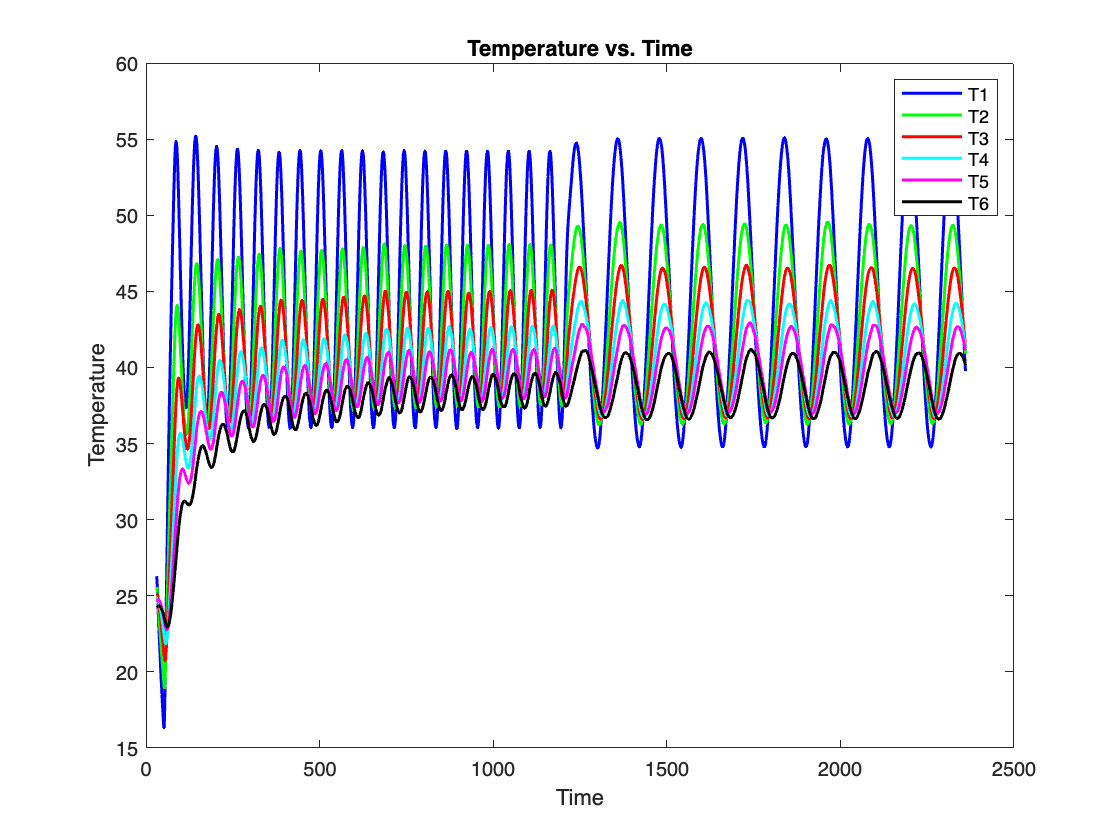

% Define the lower and upper time limits of a time interval in which
%    control parameters were constant.
% let's plot all the data to see how it looks.
lowerLimit = 30; % this was the time at which the control parameters were changed
upperLimit = 7800; % plot all the data

% Create a logical index for the specified time range
timeRange = numericData(:,3) > lowerLimit & numericData(:,3) < upperLimit;

% Extract the 6 thermistors data within the time range
tempDataInRange = numericData(timeRange, [1 5 6 7 8 9]);
time = numericData(timeRange,3);

% Plot the temperature data vs time
plot(time, tempDataInRange(:, 1), 'b', 'LineWidth', 1.5); % TEC thermistor
hold on;
plot(time, tempDataInRange(:, 2), 'g', 'LineWidth', 1.5); % T1
plot(time, tempDataInRange(:, 3), 'r', 'LineWidth', 1.5); % T2
plot(time, tempDataInRange(:, 4), 'c', 'LineWidth', 1.5); % T3
plot(time, tempDataInRange(:, 5), 'm', 'LineWidth', 1.5); % T4
plot(time, tempDataInRange(:, 6), 'k', 'LineWidth', 1.5); % T5
hold off;
% Add labels and legend
xlabel('Time');
ylabel('Temperature');
title('Temperature vs. Time');
legend('T1', 'T2', 'T3', 'T4', 'T5', 'T6');

#### Analysis

In this experiment you will measure the steady-state temperature profile of a metal rod you will also measure the oscillatory temperature profile of a thin rod. The boundary conditions are that the base of the rod is $T_{\textrm{set}}$ and the rod is in a room with temperature $T_{\infty }$.

- Read Lienhard & Lienhard chapters 1.3 & 4.5. Focus on section 4.5 - temperature profile of a thin fin.

- For the derivation of the Angstrom experiment, with a periodically varying temperature, read Carslaw and Jaeger, sec. 4.4 pl. 136 -139. The semi-infinite rod.  

- Read Angstrom's 1863 paper.

- Read the paper by Zhang et. al. on the Angstrom experiment. 

- Read the student report from the College of Wooster of Angstrom's experiment.

The heat diffusion equation describes the spatial-temporal distribution of temperature in matter.

         
$$\frac{\partial T}{\partial t}=\frac{k}{c \rho }



\frac{\partial ^2T}{\partial x^2}-\frac{H P}{c \rho A  }T=\kappa  \frac{\partial ^2T}{\partial x^2}-\nu  T$$


In steady state


$$\frac{\partial T}{\partial t}=\kappa  \frac{\partial ^2T}{\partial x^2}-\nu  T = 0$$


and


$$T(x) = T(0)e^{-q_lx}$$


with


$$q_l=\sqrt{\frac{\nu }{\kappa }} = \sqrt{\frac{HP}{k A}}$$
 

Angstrom periodically varied the temperature at the base of the rod and solved the time dependent heat equation assuming a solution of the form


$$T\left(x,t\right)=T\left(x\right)e^{i\omega t}$$


Then


$$\frac{\partial ^2T}{\partial x^2} - \frac{\nu +i\omega}{\kappa}T = 0$$


The solution of this is


$$T(x) =T(0)e^{-qx - iq'x}$$


and if the temperature at the base is sinusoidally varied about room temperature, then


$$T(x,t) =T(0)e^{-qx}\cos(\omega t -q'x+\epsilon)$$


where


$$q + iq' = \sqrt{\frac{\nu + i\omega}{\kappa}}$$


with


$$q=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}+\nu }{2 \kappa }}$$



$$

q'=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}-\nu }{2 \kappa }}$$


and


$$q q'=\frac{\omega }{2 \kappa }$$


Units are M, kg, sec, Watts, J, K etc.

$d\;\left\lbrack M\right\rbrack$  diameter of rod

$H\;\left\lbrack \frac{\mathrm{W}}{{\mathrm{M}}^{2\;} \mathrm{K}}\right\rbrack$surface conductance

$k\;\left\lbrack \frac{\mathrm{W}}{\mathrm{M}\;\mathrm{K}}\right\rbrack$thermal conductivity

$P\;\left\lbrack \mathrm{M}\right\rbrack$ perimeter

$A\;\left\lbrack {\mathrm{M}}^2 \right\rbrack$ area

$\rho \;\left\lbrack \frac{\textrm{kg}}{{\mathrm{M}}^3 }\right\rbrack$ density

$c\;\left\lbrack \frac{J}{K\;\textrm{kg}\;}\right\rbrack$ specific heat

$v=\frac{H P}{c \rho A } [1/\text{sec}]$ thermal loss rate

$\kappa =\frac{k}{c \rho } \left[\frac{M^2}{\text{sec}}\right]$  thermal diffusion constant

#### values for aluminum

$\rho =2700\;\left\lbrack \frac{\textrm{kg}}{{\mathrm{M}}^3 }\right\rbrack \;\;\;$density

$c=900\;\left\lbrack \frac{J}{K\;\textrm{kg}}\right\rbrack$   specific heat

$d=\frac{1}{2\;}\textrm{inch}$ diameter

At the base of the rod apply the following time-dependent boundary condition:

              
$$\tau (0,t)=T_0+\text{$\Delta $T} \cos (\text{$\omega $t})$$


The solution for the difference in the temperature of the rod, $T\left(x,t\right)$, and lab, $T_{\infty }$,  is 

              
$$T

(

\text{\textit{x,t}}

\text{) - }

T_{\infty }

\text{ = $\tau $(}

x

,

t

\text{) = }

\left(T_0-T_{\infty }\right) e^{ -q_l x}+\text{$\Delta $T} e^{-q x} \cos \left(\omega t- q' x \right)$$


What happens for the non-oscillatory case of $\omega$ = 0? 

### Assignment

(0) How good are the thermistors? Are they repeatable? How much variability is there between them? How do you check? Where is the error coming from? The thermistors themselves, or fixed resistors, or the A/D conversion? How can you correct for the errors?

(1) Do the steady-state experiment by setting the base temperature to 60C and measuring the temperature along the rod. This is the experiment described by Abu-Mulaweh and in sec. 4.5 in Lienhard & Lienhard.

(2) Plot experiment and theory and obtain $\frac{1}{q_l }$.

(3) For the derivation of the Angstrom experiment with a periodically varying temperature, read [Carslaw and Jaeger, sec. 4.4 pl. 136 -139](http://216.92.172.113/courses/phys39/Thermal%20Measurement/conduction-of-heat-in-solids-carslaw-and-jaeger.pdf). The semi-infinite rod.

(4) First, use only proportional control and carefuly observe the temporally sinusoidal varying temperature. You will notice that the heating and cooling portions of the temperature are different. You observed that dT / dPWM was different for heating and cooling. Can you figure out how to modify the Arduino code to correct this and make the temperature profile closer to a sinusoid?

(5) Next, use integral control on the sinusoidal varying temperature profile. Under what conditions will the measured temperature accurately track the set temperature? What temperature amplitudes and period? Does it matter that dT / dPWM is different for heating and cooling when using integral control?  

(6) Now do the oscillatory case. Set $T_{0\;} =$45 C. Oscillate temp with an amplitude of 10 degrees and a period between 60 s and 240 s, say 60, 120, 180, 240 seconds for the 1/2 inch diameter aluminum rod. To simplify results you can set $T_{0\;} =T_{\infty }$, but you probably should adjust the amplitude. How well does your controller perform? Tweak the PID settings to optimize temperature. Measure the temperature at 3 to 5 locations starting with the lowest hole near the bottom of rod. Make sure that the amplitude of the smallest measured temperature is at least 1C. Check that rod is at room temp at tip. Ideally, one would fit all data sets simultaneously to model, which has a bunch of fit parameters. Vary period and see if same thermal conductivity results are obtained. 

For each position, $x_i$, wait until the temperature settles into a periodic state and the base stops drifting. Collect data for at least 5 periods. 

 (7a) Fit the oscillating temperature to

                                   $T(x_i,t)=A_i+B_i \cos  \left( \omega t + \epsilon _i\right)$.

Say you measure at 4 positions, $x_i$. Then fit the 4 values of $A_i$, $B_i$ and $\varepsilon_i$.

$
A_i = 
(T_0-T_{\infty }) e^{- q_lx_i + \delta }  \text{ with }

q_l=\sqrt{\frac{\nu }{\kappa }}$ ,

$\delta$ is just some constant since we don't exactly know where the zero point is located. For now, we take the first thermistor located in the rod, above the TEC as location of the base of the rod, that is$\;\textrm{at}\;x_2 =0,$ $\delta =0$.   

$B_i = 

\text{$\Delta $T} e^{ -q x_i + \delta}

\text{ with }

q=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}+\nu }{2 \kappa }}$,  

and

$\epsilon_i = \epsilon -q' x_i 

\text{ with }

q'=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}-\nu }{2 \kappa }}$.  

$\varepsilon$ is just some constant since we don't exactly know when was the beginning of the experiment so we don't know the initial phase of the oscillation.

(7b) Make separate plots for the data and fits to temperature vs time for each thermistor.

(7c) Calculate $\kappa \;\textrm{and}\;\nu$. Note that $q q'=\frac{\omega }{2 \kappa }$! 

Once you have $\kappa$ you can get $\nu$. Now repeat as a function of frequency $\omega$ and plot $q q' \text{ vs } \omega $. 

Extract $\kappa$. Next deduce $\nu$ from measurements of $q\left(\omega \right)$ and $q^{\prime } \left(\omega \right)$. Plot and fit $\frac{q^{\prime } }{q}$ vs. $\omega$ to obtain $\nu$.

(8) Plot the experimental values of $\frac{1}{q_l }$, $\frac{1}{q}$, and $\frac{2\pi }{q^{\prime } }$ vs. $\omega$. Compare with theory on same plot.

(9) Plot the data, $T\left(x,t\right)$ for different frequencies.

(10) What are the values for surface conductance, $H\;\left\lbrack W\;/{\;\mathrm{M}}^{2\;} \mathrm{K}\right\rbrack ,$  and for thermal conductivity, $k$ [W / M K]? How do they compare with published data for aluminum? 

(11) Measure the heat flux into the fin at steady state.

(12) Given a fixed mass of aluminum, what is the optimal shape and number of fins to maximize the cooling power of the fins? Google images "pin fin" . Explain why this design is chosen to cool chips. How many watts can be dissipated with these devices?

% enter period of oscillation
period = 60; % period of oscillation in seconds

% Define the lower and upper time limits of a time interval in which
%    control parameters were constant.
lowerLimit = 800; % this was the time at which the control parameters were changed
upperLimit = 1000; % this was the next time at which the control parameters were changed

% Create a logical index for the specified time range
timeRange = numericData(:,3) > lowerLimit & numericData(:,3) < upperLimit;

% Extract the 6 thermistors data within the time range
tempDataInRange = numericData(timeRange, [1 5 6 7 8 9]);
time = numericData(timeRange,3);

% Assuming a known frequency w, define your custom model function
w = 2 * pi / period; % Convert the period to radians per second

% Define the equation expression for the fit
fitEquation = fittype('A + B * cos(w * t + epsilon)', 'independent', 't', 'problem', {'w'},'coefficients', {'A', 'B', 'epsilon'});

% Now, use this fit type to fit the data


% Initialize arrays to store the fit parameters
A = zeros(6, 1);
B = zeros(6, 1);
epsilon = zeros(6, 1);


% Fit each temperature vs. time pair
for i = 1:6
    [AngFit{i}, gof{i}] = fit(time, tempDataInRange(:, i), fitEquation, 'problem', {w}, 'StartPoint', [45 10 pi]);
    A(i,1) = AngFit{i}.A;
    B(i,1) = AngFit{i}.B;
    epsilon(i,1) = AngFit{i}.epsilon;
end

% Display the results
disp('Fitted Parameters:');

Fitted Parameters:


disp(['A1: ', num2str(A(1))]);

A1: 44.9905


disp(['B1: ', num2str(B(1))]);

B1: 9.0453


disp(['Epsilon1: ', num2str(epsilon(1))]);

Epsilon1: 3.7802


disp(['A2: ', num2str(A(2))]);

A2: 42.6901


disp(['B2: ', num2str(B(2))]);

B2: 5.2528


disp(['Epsilon2: ', num2str(epsilon(2))]);

Epsilon2: 3.5132


disp(['A3: ', num2str(A(3))]);

A3: 41.3871


disp(['B3: ', num2str(B(3))]);

B3: 3.5657


disp(['Epsilon3: ', num2str(epsilon(3))]);

Epsilon3: 3.1267


disp(['A4: ', num2str(A(4))]);

A4: 40.1869


disp(['B4: ', num2str(B(4))]);

B4: 2.4052


disp(['Epsilon4: ', num2str(epsilon(4))]);

Epsilon4: 2.7677


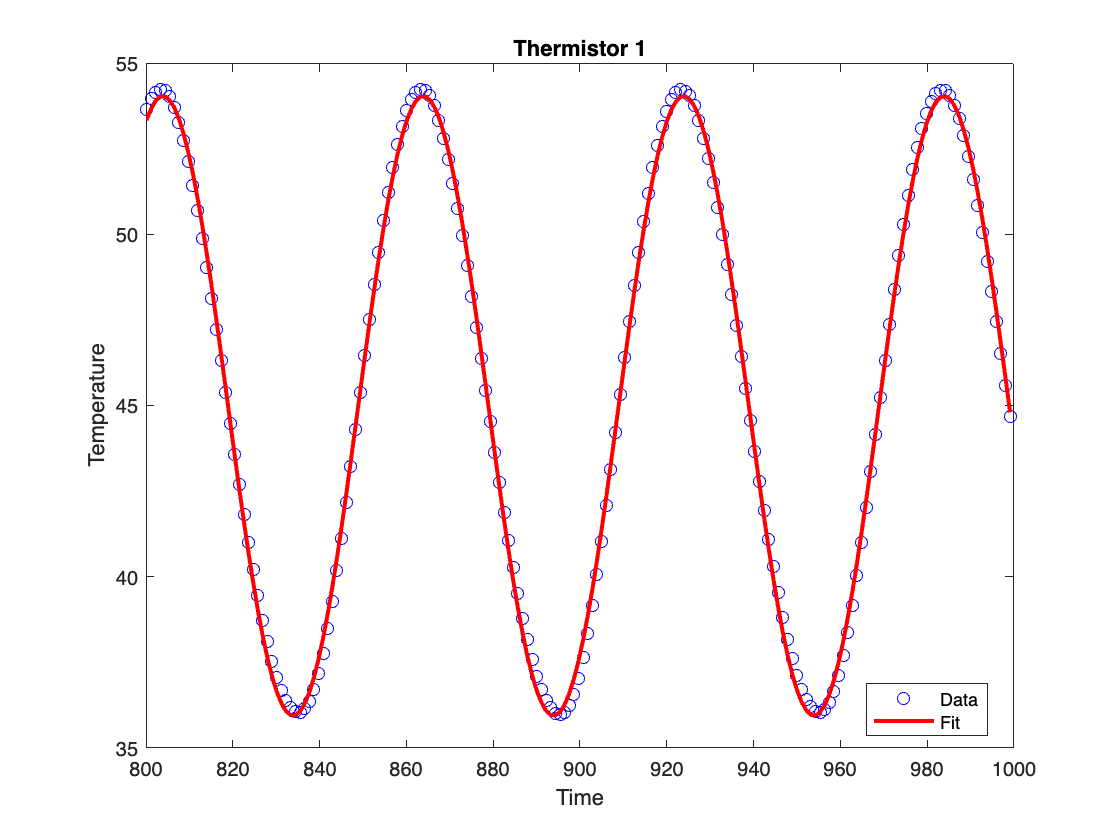

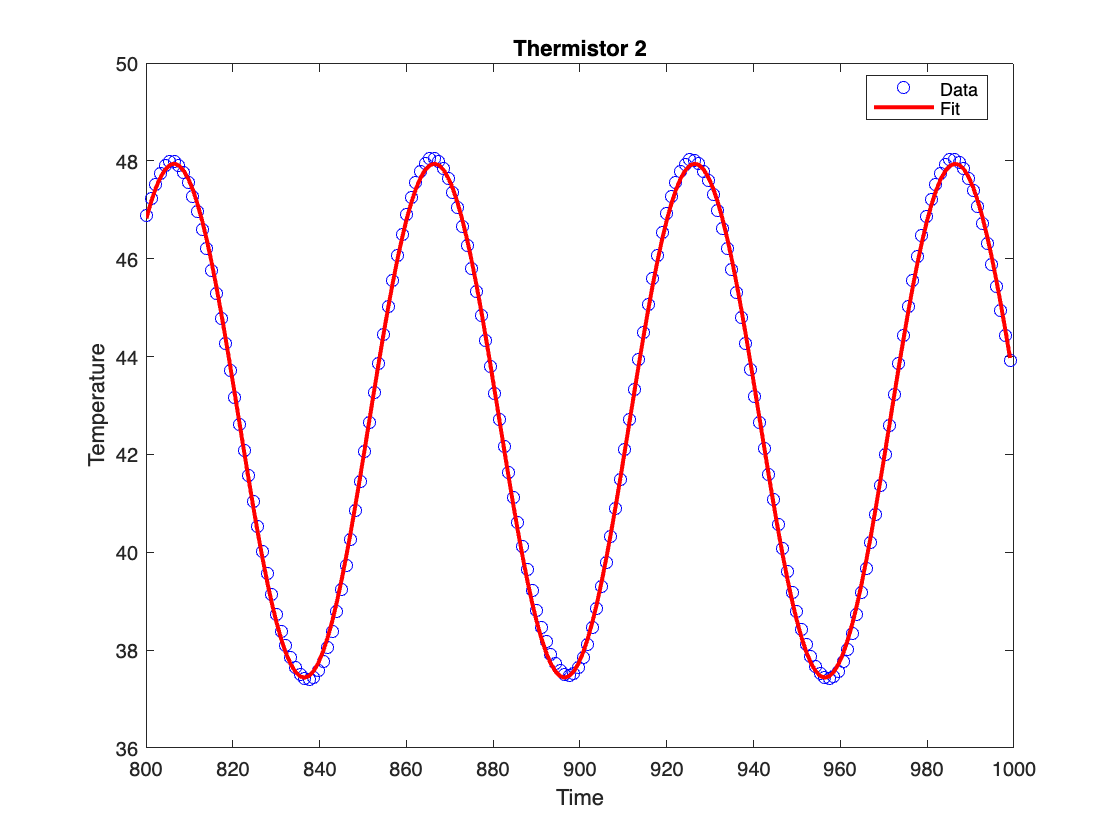

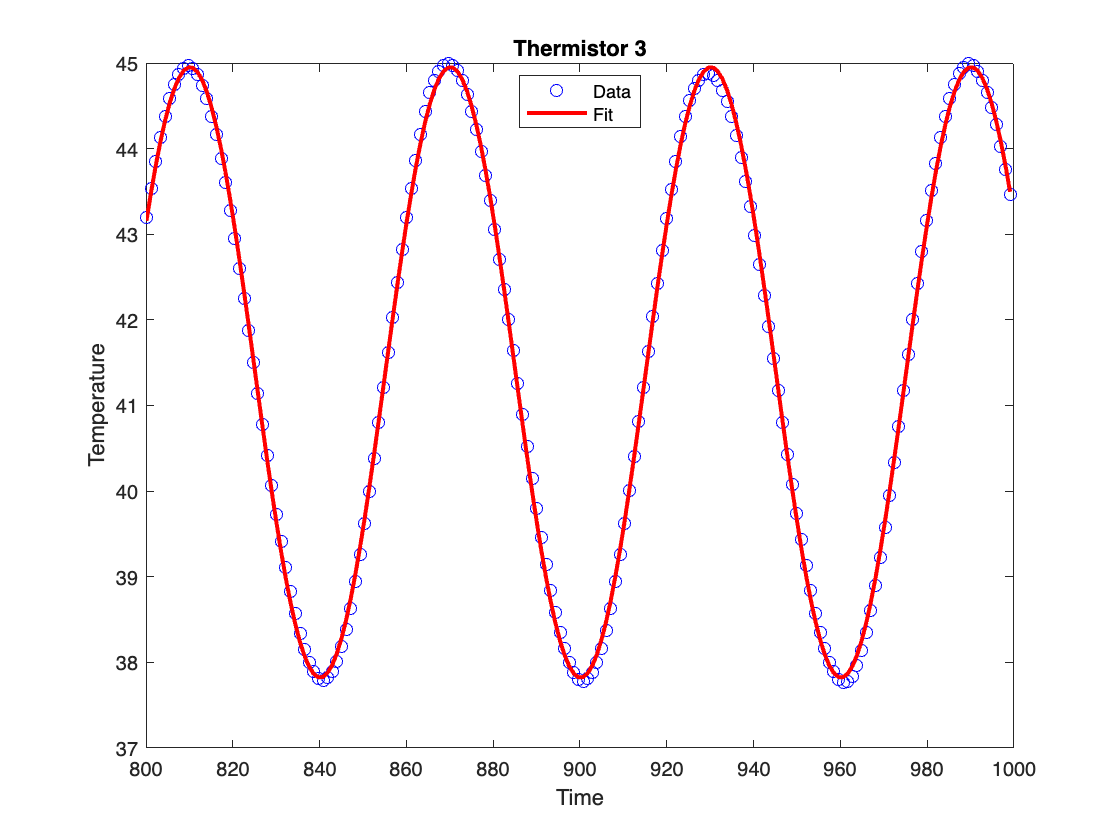

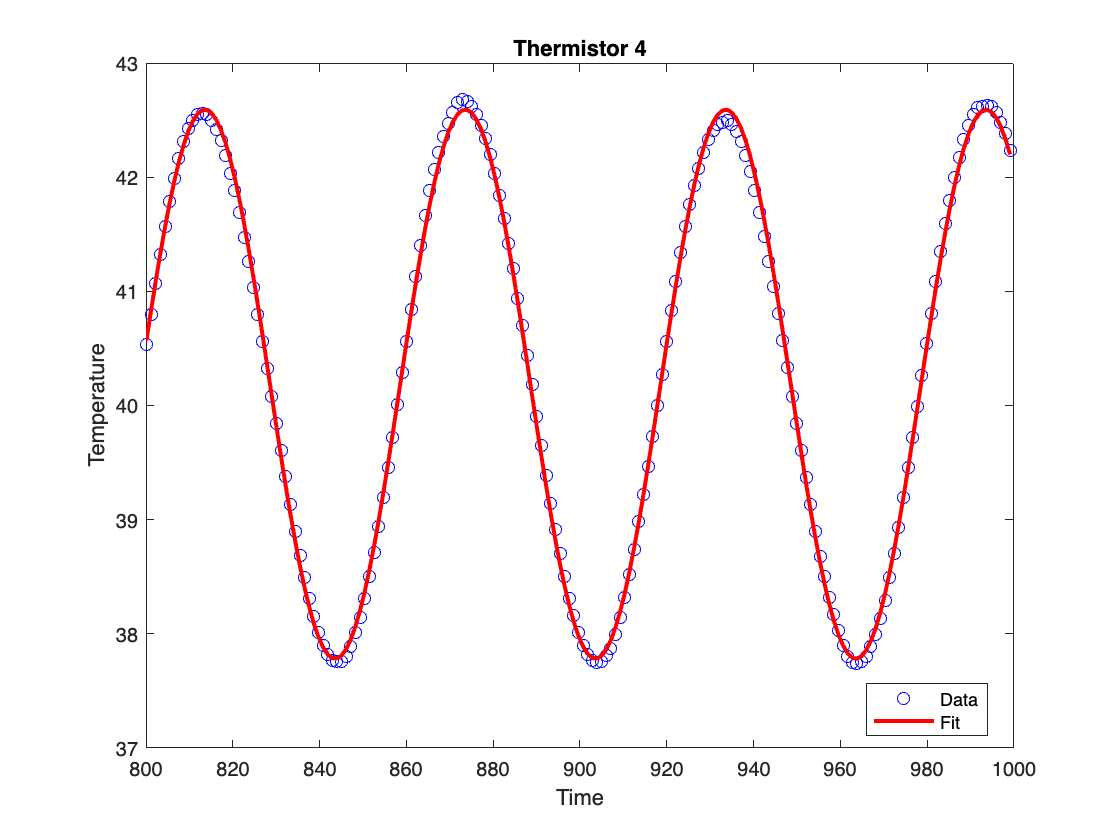

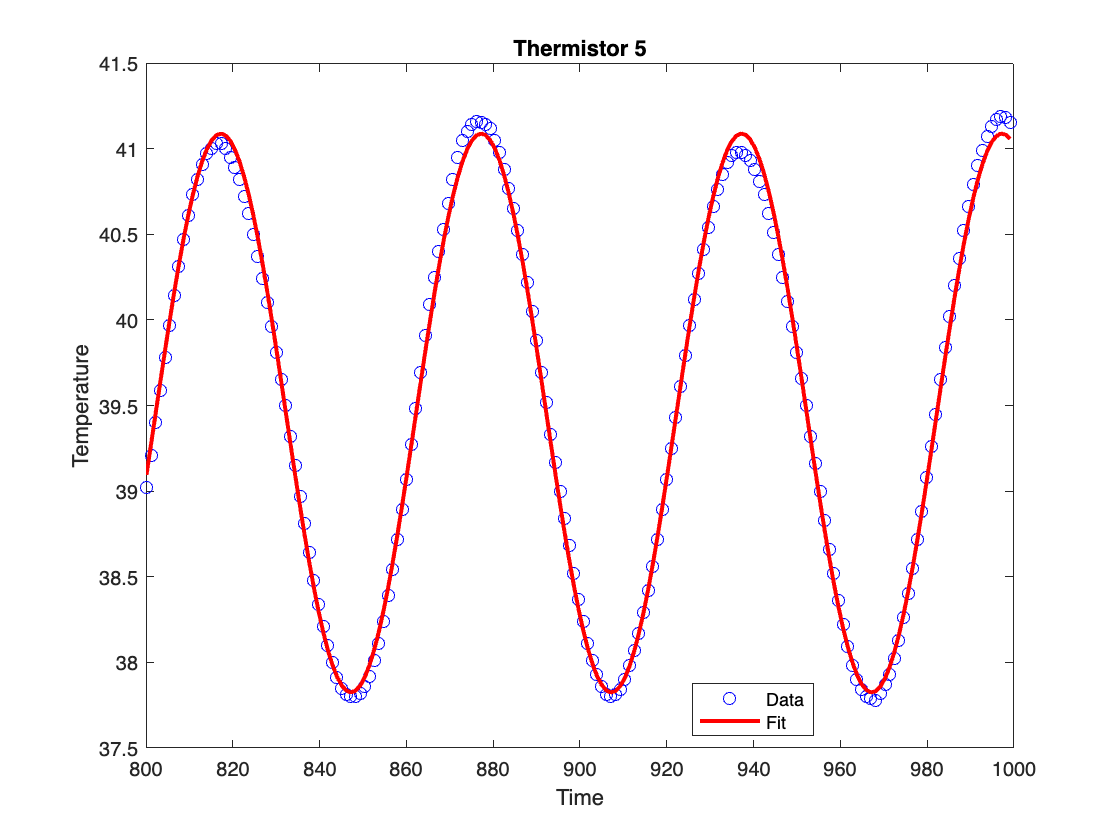

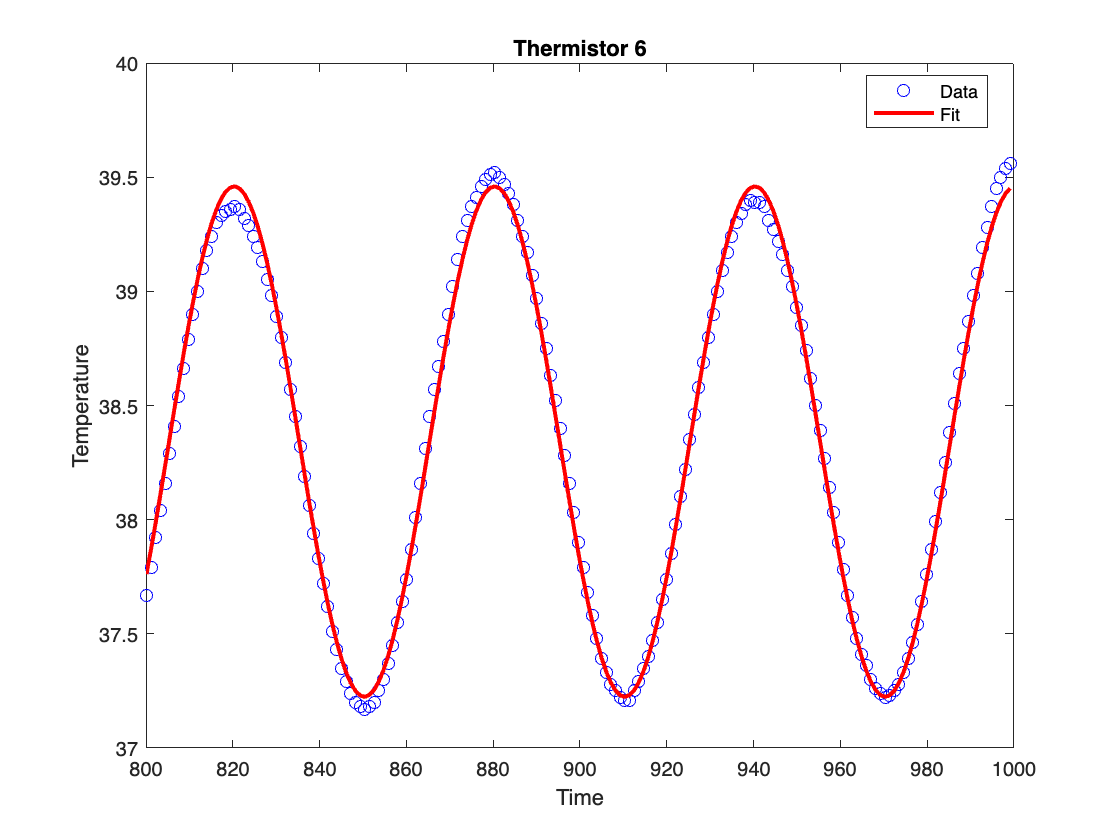

% Assuming you have fitted the data for each thermistor as AngFit{i}

% Iterate through each thermistor's data and fit
for i = 1:6
    figure;  % Create a new figure for each pair of data and fit

    % Plot the data points
    plot(time, tempDataInRange(:, i), 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    A = AngFit{i}.A;
    B = AngFit{i}.B;
    epsilon = AngFit{i}.epsilon;

    % Generate the fit curve using the model
    fitCurve = A + B * cos(w * time + epsilon);

    % Plot the fit curve
    plot(time, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title(['Thermistor ' num2str(i)]);
    xlabel('Time');
    ylabel('Temperature');
    legend('Location', 'best');

    hold off;
end

Fit the $A_i$


$$
A_i = 
(T_0-T_{\infty }) e^{- q_l (x_i + \delta) } = T  e^{- q_l (x_i + \delta) } \text{ with }

q_l=\sqrt{\frac{\nu }{\kappa }}$$


The fitting parameters are $T,q_l$, and $\delta$.

For now, $\delta =0$.

The data in AngFit{1}.A is the TEC. We will use the three values AngFit{2}.A, AngFit{3}.A and AngFit{4}.A

The locations of these thermistors are at x = 0, 12.7 mm, and 25.4 mm along the rod. We consider the location of the first measurment thermistor to define x = 0. 

% Define the equation expression for the fit
%fitEqA = fittype('T * exp(-(ql * (x + del)) )', 'independent', 'x','coefficients', {'T', 'ql', 'del'});
fitEqA = fittype('T * exp(-(ql * (x)) )', 'independent', 'x','coefficients', {'T', 'ql'});

% locations of thermistors
x = [0 12.7e-3 25.4e-3 38.1e-3 50.8e-3]'

x =          0
    0.0127
    0.0254
    0.0381
    0.0508


Aarray = [AngFit{2}.A AngFit{3}.A AngFit{4}.A AngFit{5}.A AngFit{6}.A]'

Aarray =    42.6901
   41.3871
   40.1869
   39.4563
   38.3421



% Fit  vs. x 

[AFit, Agof] = fit(x, Aarray, fitEqA, 'StartPoint', [43 4]);

% Display the results
disp('Fitted Parameters:');

Fitted Parameters:


disp(['T: ', num2str(AFit.T)]);

T: 42.5694


disp(['ql: ', num2str(AFit.ql)]);

ql: 2.0745


%disp(['del: ', num2str(AFit.del)]);

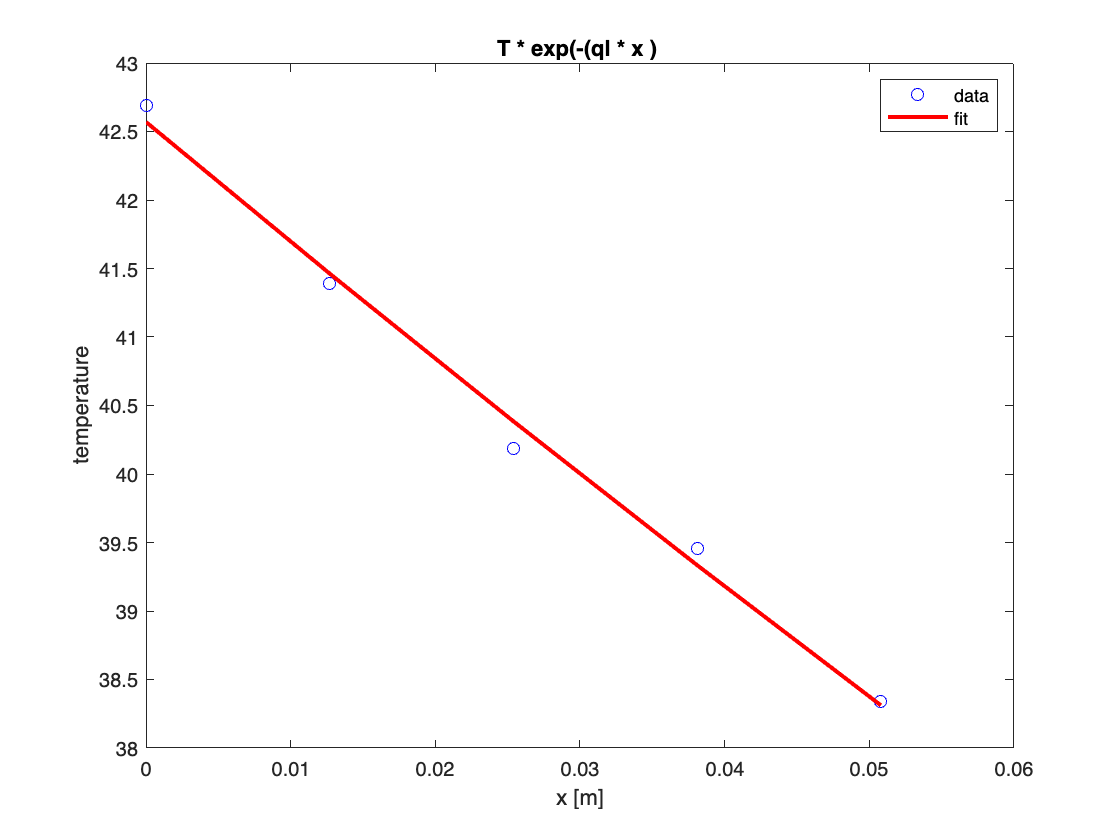

% plot the data and fit

    % Plot the data points
    plot(x, Aarray, 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    T = AFit.T;
    ql = AFit.ql;
%    del = AFit.del;

    % Generate the fit curve using the model
    fitCurve = T * exp(-(ql * (x)) );

    % Plot the fit curve
    plot(x, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title(['T * exp(-(ql * x ) ']);
    xlabel('x [m]');
    ylabel('temperature');
    legend('data', 'fit');

    hold off;

Fit the $B_i$

$B_i = 

\text{$\Delta $T} e^{ -q x_i + \delta}

\text{ with }

q=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}+\nu }{2 \kappa }}$, 

The fitting parameters are $\Delta T\;\textrm{and}\;q$.

For now, $\delta =0$.

The data in AngFit{1}.B is the TEC. We will use the three values AngFit{2}.B, AngFit{3}.B and AngFit{4}.B

The locations of these thermistors are at x = 0, 12.7 mm, and 25.4 mm along the rod. We consider the location of the first measurment thermistor to define x = 0. 

% Define the equation expression for the fit
%fitEqA = fittype('T * exp(-(ql * (x + del)) )', 'independent', 'x','coefficients', {'T', 'ql', 'del'});
fitEqB = fittype('T * exp(-(q * (x)) )', 'independent', 'x','coefficients', {'T', 'q'});

% locations of thermistors
x = [0 12.7e-3 25.4e-3 38.1e-3 50.8e-3]'

x =          0
    0.0127
    0.0254
    0.0381
    0.0508


Barray = [AngFit{2}.B AngFit{3}.B AngFit{4}.B AngFit{5}.B AngFit{6}.B]'

Barray =     5.2528
    3.5657
    2.4052
    1.6319
    1.1178



% Fit  vs. x 

[BFit, Bgof] = fit(x, Barray, fitEqB, 'StartPoint', [10 2]);

% Display the results
disp('Fitted Parameters:');

Fitted Parameters:


disp(['Del T: ', num2str(BFit.T)]);

Del T: 5.2532


disp(['q: ', num2str(BFit.q)]);

q: 30.6225


%disp(['del: ', num2str(AFit.del)]);

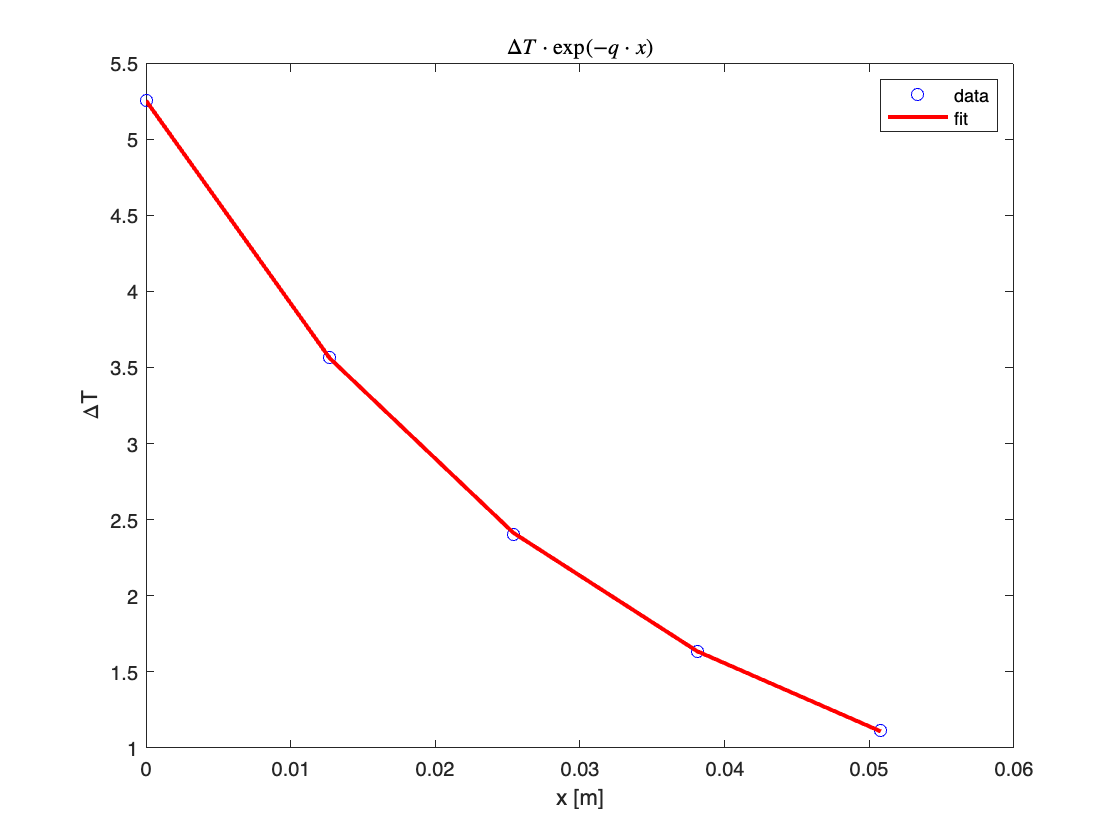

% plot the data and fit

    % Plot the data points
    plot(x, Barray, 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    T = BFit.T; % Del T (amplitude of sin)
    q = BFit.q;
%    del = AFit.del;

    % Generate the fit curve using the model
    fitCurve = T * exp(-(q * (x)) );

    % Plot the fit curve
    plot(x, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title('$\Delta T \cdot \exp(-q \cdot x)$', 'Interpreter', 'latex');

    xlabel('x [m]');
    ylabel('\DeltaT');
    legend('data', 'fit');

    hold off;

Fit the $\varepsilon_i$.

$\epsilon_i = \epsilon -q' x_i 

\text{ with }

q'=\sqrt{\frac{\sqrt{\nu ^2+\omega ^2}-\nu }{2 \kappa }}$.  

The data in AngFit{1}.epsilon is at the TEC. We will use the three values AngFit{2}.epsilon, AngFit{3}.epsilon and AngFit{4}.epsilon

The locations of these thermistors are at x = 0, 12.7 mm, and 25.4 mm along the rod. We consider the location of the first measurment thermistor to define x = 0. 

  % Define the equation expression for the fit
fitEqEpsilon = fittype('epsi - qp * x', 'independent', 'x','coefficients', {'epsi', 'qp'});

% locations of thermistors
x = [0 12.7e-3 25.4e-3 38.1e-3 50.8e-3]'

x =          0
    0.0127
    0.0254
    0.0381
    0.0508


Epsilonarray = [AngFit{2}.epsilon AngFit{3}.epsilon AngFit{4}.epsilon AngFit{5}.epsilon AngFit{6}.epsilon]'

Epsilonarray =     3.5132
    3.1267
    2.7677
    2.3840
    2.0610



% Fit  vs. x 

[EpsilonFit, Epsilongof] = fit(x, Epsilonarray, fitEqEpsilon, 'StartPoint', [3.5 40]);

% Display the results
disp('Fitted Parameters:');

Fitted Parameters:


disp(['eps: ', num2str(EpsilonFit.epsi)]);

eps: 3.4999


disp(['qp: ', num2str(EpsilonFit.qp)]);  

qp: 28.7172


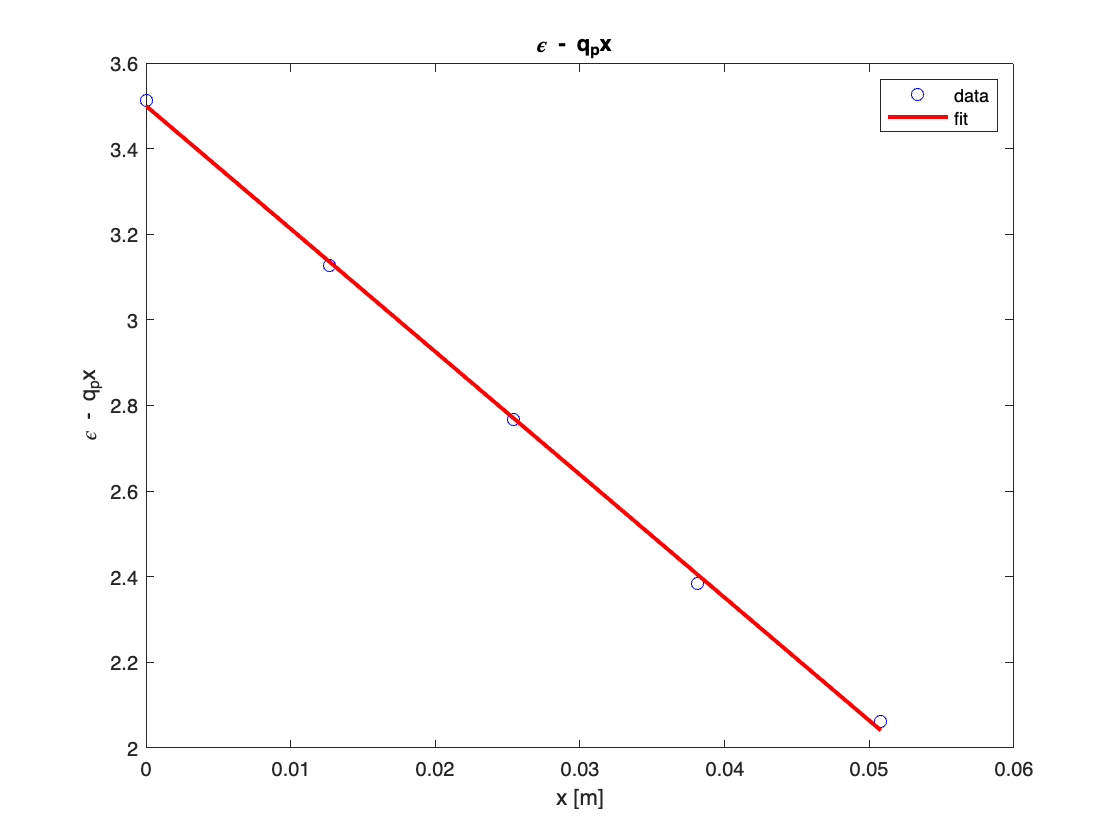

% plot the data and fit

    % Plot the data points
    plot(x, Epsilonarray, 'bo', 'DisplayName', 'Data');
    hold on;

    % Calculate the fit values based on the model
    epsi = EpsilonFit.epsi;
    qp = EpsilonFit.qp;


    % Generate the fit curve using the model
    fitCurve = epsi - qp * x;

    % Plot the fit curve
    plot(x, fitCurve, 'r-','LineWidth', 2, 'DisplayName', 'Fit');

    % Label the plot
    title(['\epsilon - q_px ']);
    xlabel('x [m]');
    ylabel('\epsilon - q_px');
    legend('data', 'fit');

    hold off;


$$q q'=\frac{\omega }{2 \kappa }$$



$$\kappa = \frac{\omega}{2 q q'}$$


$\kappa =\frac{k}{c \rho } \left[\frac{M^2}{\text{sec}}\right]$  thermal diffusion constant

$k\;\left\lbrack \frac{\mathrm{W}}{\mathrm{M}\;\mathrm{K}}\right\rbrack$thermal conductivity


$$k = \kappa c \rho =  \frac{\omega c \rho}{2 q q'}$$


#### values for aluminum

$\rho =2700\;\left\lbrack \frac{\textrm{kg}}{{\mathrm{M}}^3 }\right\rbrack \;\;\;$density

$c=900\;\left\lbrack \frac{J}{K\;\textrm{kg}}\right\rbrack$   specific heat

$d=\frac{1}{2\;}\textrm{inch}$ diameter

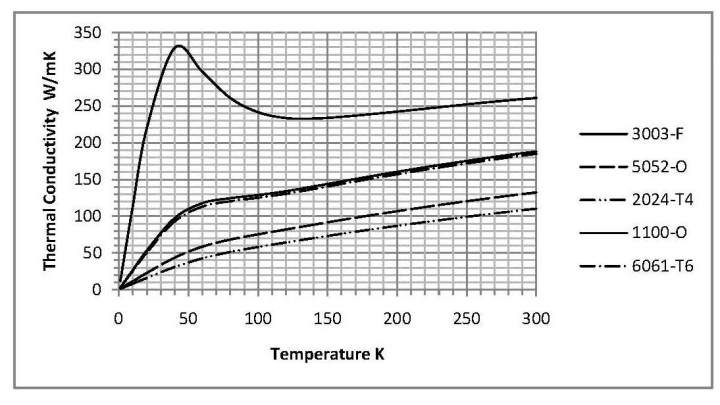

Thermal conductivity for several aluminum alloys.

w = 2*pi/period;  % frequence in radians / sec
c = 900; % specific heat
rho = 2700; % density
k = w*c*rho/(2*q*qp); % [W/M*K]
disp(['thermal conductivity k [W/M*K]: ', num2str(k)]);  

thermal conductivity k [W/M*K]: 144.6849
